# explore and compare the observational and TNG mass functions

We explore the observational mass function for satellites and centrals to make an informed decision as to how to cut the galaxy sample

## read in catalogs

% location 
catPath='/home/zinger/workProjects/IllustrisTNG/obsComparison';

% load Obs. catalog 
cname='cgmGalaxyQsoFilamentYangGroups_rho1Mpc_h1meas.fits'; %yangGroup_alfalfa_crossmatch.fits';
obsCat=fitsread([catPath '/' cname],'binarytable');
catInfo=fitsinfo([catPath '/' cname]);

obs.mstar=obsCat{8};
obs.mhalo=obsCat{23};
obs.rpos=obsCat{48};
obs.isCentral=obsCat{50};

% load TNG catalogs

tng100cat=illustris.utils.read_catalog('StellarMassCatalog_TNG100_099','fullpath',catPath);
tng300cat=illustris.utils.read_catalog('StellarMassCatalog_TNG300_099','fullpath',catPath);
tng50cat=illustris.utils.read_catalog('StellarMassCatalog_TNG50_099','fullpath',catPath);


## plot TNG mass functions

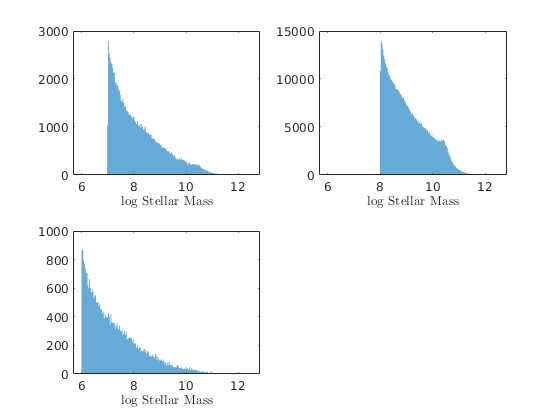

bEdge=linspace(6,12.5,200);

subplot(2,2,1)
hs100=histogram(log10(tng100cat.StellarMass),bEdge,'edgecolor','none');
xlabelmine('log Stellar Mass');
subplot(2,2,2)
hs300=histogram(log10(tng300cat.StellarMass),bEdge,'edgecolor','none');
xlabelmine('log Stellar Mass');
subplot(2,2,3)
hs50=histogram(log10(tng50cat.StellarMass),bEdge,'edgecolor','none');
xlabelmine('log Stellar Mass');

How should we normalize? lets try dividing by total area . 

figure;
subplot(4,2,1)
h=[];
h(1)=bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./sum(hs100.Values),'EdgeColor','none',...
    'DisplayName','TNG100');
hold on
h(2)=bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./sum(hs300.Values),'EdgeColor','none','facealpha',0.5,...
    'DisplayName','TNG300');
h(3)=bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./sum(hs50.Values),'EdgeColor','none','facealpha',0.5,...
    'DisplayName','TNG50');
hl=legend(h,'fontsize',14,'Interpreter','latex');

hl =   Legend (TNG100, TNG300, TNG50) with properties:

         String: {'TNG100'  'TNG300'  'TNG50'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 14
       Position: [0.2345 0.7416 0.2163 0.1719]
          Units: 'normalized'

  Show all properties


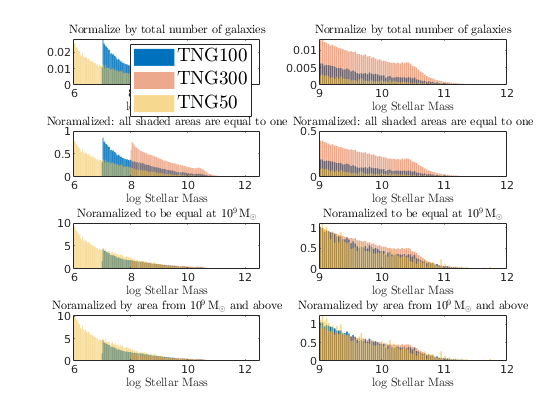

xlabelmine('log Stellar Mass');
titlemine('Normalize by total number of galaxies');

subplot(4,2,2)
bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./sum(hs100.Values),'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./sum(hs300.Values),'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./sum(hs50.Values),'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
titlemine('Normalize by total number of galaxies');
xlim([9 12])

subplot(4,2,3)
norm100=trapz(hs100.BinWidth,hs100.Values);
norm300=trapz(hs300.BinWidth,hs300.Values);
norm50=trapz(hs50.BinWidth,hs50.Values);

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
titlemine('Noramalized: all shaded areas are equal to one');

subplot(4,2,4)
bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
titlemine('Noramalized: all shaded areas are equal to one');
xlim([9 12])

subplot(4,2,5)
ind=find(bEdge>9,1,'first');

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./hs100.Values(ind),'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./hs300.Values(ind),'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./hs50.Values(ind),'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
titlemine('Noramalized to be equal at $10^9\,\mathrm{M_\odot}$');

subplot(4,2,6)

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./hs100.Values(ind),'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./hs300.Values(ind),'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./hs50.Values(ind),'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
xlim([9 12])
titlemine('Noramalized to be equal at $10^9\,\mathrm{M_\odot}$');

subplot(4,2,7)
norm100=trapz(hs100.BinWidth,hs100.Values(ind:end));
norm300=trapz(hs300.BinWidth,hs300.Values(ind:end));
norm50=trapz(hs50.BinWidth,hs50.Values(ind:end));

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
titlemine('Noramalized by area from $10^9\,\mathrm{M_\odot}$ and above');

subplot(4,2,8)

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.5)
xlim([9 12])
xlabelmine('log Stellar Mass');
titlemine('Noramalized by area from $10^9\,\mathrm{M_\odot}$ and above');

## this seems like a winner

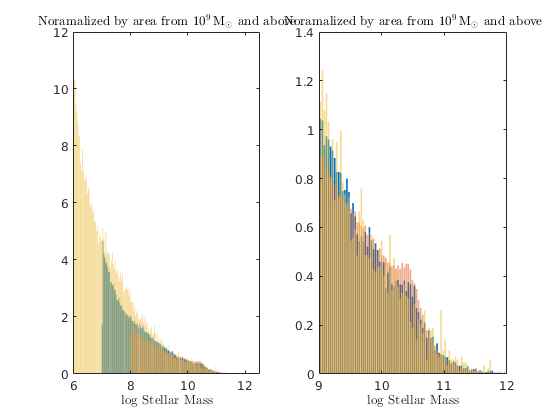


figure
subplot(1,2,1)
norm100=trapz(hs100.BinWidth,hs100.Values(ind:end));
norm300=trapz(hs300.BinWidth,hs300.Values(ind:end));
norm50=trapz(hs50.BinWidth,hs50.Values(ind:end));

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.5)
xlabelmine('log Stellar Mass');
titlemine('Noramalized by area from $10^9\,\mathrm{M_\odot}$ and above');

subplot(1,2,2)

bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none')
hold on
bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.5)
bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.5)
xlim([9 12])
xlabelmine('log Stellar Mass');
titlemine('Noramalized by area from $10^9\,\mathrm{M_\odot}$ and above');

## lets add the obs using the same normalization 

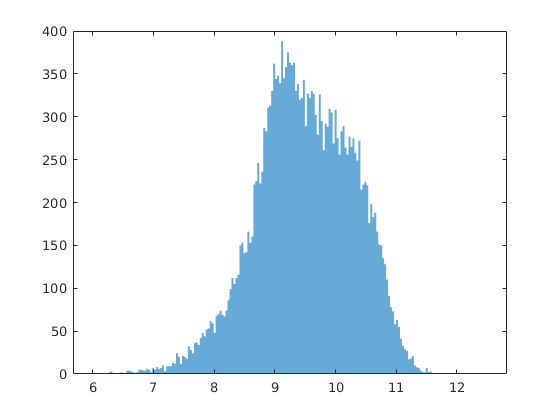

figure
ind=find(bEdge>9.2,1,'first');
norm100=trapz(hs100.BinWidth,hs100.Values(ind:end));
norm300=trapz(hs300.BinWidth,hs300.Values(ind:end));
norm50=trapz(hs50.BinWidth,hs50.Values(ind:end));

hsObs=histogram(obs.mstar,bEdge,'edgecolor','none');

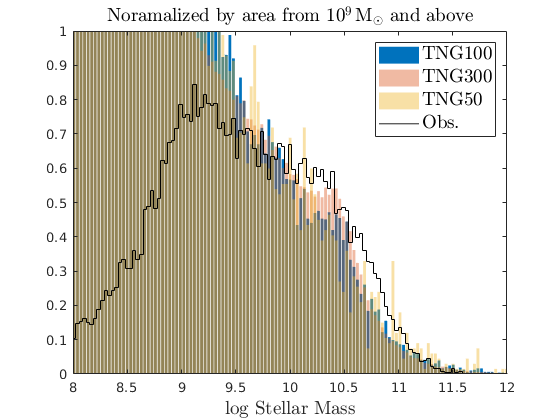

normObs=trapz(hsObs.BinWidth,hsObs.Values(ind:end));

figure

h(1)=bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none',...
    'DisplayName','TNG100');
hold on
h(2)=bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.4,...
    'DisplayName','TNG300');
h(3)=bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.4,...
    'DisplayName','TNG50');

%bar(hsObs.BinEdges(1:end-1)+0.5.*hsObs.BinWidth,hsObs.Values./normObs,'EdgeColor','none','facealpha',0.8)
h(4)=stairs(hsObs.BinEdges(1:end-1),hsObs.Values./normObs,'Color','k',...
    'DisplayName','Obs.');

xlim([8 12])
ylim([0 1])
hl=legend(h,'Fontsize',14,'Interpreter',"latex");
xlabelmine('log Stellar Mass');
titlemine('Noramalized by area from $10^9\,\mathrm{M_\odot}$ and above');

## lets look at centrals and satellites

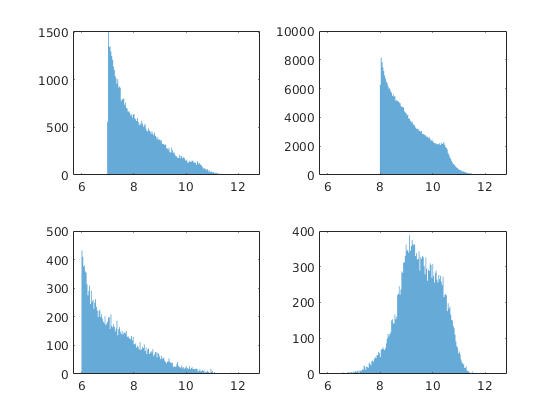

% centrals 
ind=find(bEdge>9.2,1,'first');

figure
subplot(2,2,1)
msk=logical(tng100cat.isCentral);
hs100=histogram(log10(tng100cat.StellarMass(msk)),bEdge,'edgecolor','none');
norm100=trapz(hs100.BinWidth,hs100.Values(ind:end));

subplot(2,2,2)
msk=logical(tng300cat.isCentral);
hs300=histogram(log10(tng300cat.StellarMass(msk)),bEdge,'edgecolor','none');
norm300=trapz(hs300.BinWidth,hs300.Values(ind:end));

subplot(2,2,3)
msk=logical(tng50cat.isCentral);
hs50=histogram(log10(tng50cat.StellarMass(msk)),bEdge,'edgecolor','none');
norm50=trapz(hs50.BinWidth,hs50.Values(ind:end));

subplot(2,2,4)
msk=logical(obs.isCentral);
hsObs=histogram(obs.mstar(msk),bEdge,'edgecolor','none');

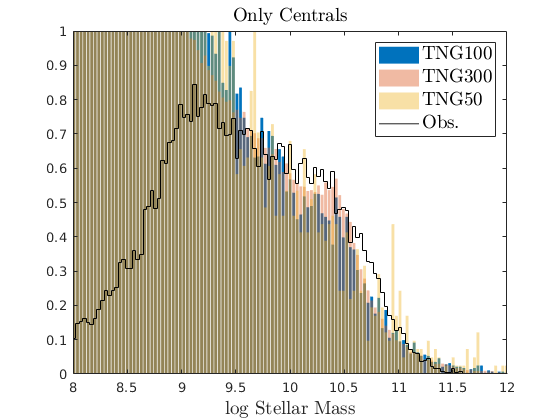

normObs=trapz(hsObs.BinWidth,hsObs.Values(ind:end));

figure

h(1)=bar(hs100.BinEdges(1:end-1)+0.5.*hs100.BinWidth,hs100.Values./norm100,'EdgeColor','none',...
    'DisplayName','TNG100');
hold on
h(2)=bar(hs300.BinEdges(1:end-1)+0.5.*hs300.BinWidth,hs300.Values./norm300,'EdgeColor','none','facealpha',0.4,...
    'DisplayName','TNG300');
h(3)=bar(hs50.BinEdges(1:end-1)+0.5.*hs50.BinWidth,hs50.Values./norm50,'EdgeColor','none','facealpha',0.4,...
    'DisplayName','TNG50');

%bar(hsObs.BinEdges(1:end-1)+0.5.*hsObs.BinWidth,hsObs.Values./normObs,'EdgeColor','none','facealpha',0.8)
h(4)=stairs(hsObs.BinEdges(1:end-1),hsObs.Values./normObs,'Color','k',...
    'DisplayName','Obs.');

xlim([8 12])
ylim([0 1])
hl=legend(h,'Fontsize',14,'Interpreter',"latex");
xlabelmine('log Stellar Mass');
titlemine('Only Centrals');